## Load Data

try
    % Prompt user to select a MAT file
    [filename, path] = uigetfile('*.mat', 'Select a MAT file');
    
    % Check if the user canceled the dialog
    if isequal(filename, 0) || isequal(path, 0)
        disp('File selection canceled. Exiting...');
        return;
    end
    
    % Load data using matfile (lightweight reference)
    matObj = matfile(fullfile(path, filename));
    
    % Access specific variables
    if isprop(matObj, 'data')
        data = matObj.data;
    else
        error('Variable ''data'' not found in the MAT file.');
    end
    
    if isprop(matObj, 'config')
        config = matObj.config;
    else
        error('Variable ''config'' not found in the MAT file.');
    end
    
    % Now you can work with 'data' and 'config'
    disp('Data loaded successfully!');
    
catch ME
    % Handle any errors
    disp(['Error: ' ME.message]);
end

Data loaded successfully!


## Format Data

fileID = filename(1:5);
transientPoints = config.FPOINTS;
dataCols = size(data,2);
sweepNum = max(data(:,1))+1;
n0Idx = max(data(:,2))+1;
p0Idx = max(data(:,3))+1;

% Reshape data N-D array
dataS = reshape(data,transientPoints,sweepNum,p0Idx,n0Idx,dataCols);

% THz data col
ThzCols = [10 11]; % I X: 10 and Y: 11

% Smooth data
dataS(:,:,:,:,ThzCols) = smoothdata(dataS(:,:,:,:,ThzCols),'sgolay',10);

% Shift zero
dataS(:,:,:,:,ThzCols) = dataS(:,:,:,:,ThzCols)-mean(dataS(1:10,:,:,:,ThzCols),1);

% Rotate data
dataSp = permute(dataS(:,:,:,:,ThzCols),[1 5 2 3 4]);
[maxValX,maxIdxX] = max(dataSp(:,1,:,:,:));
[maxValY,maxXIdxY] = max(dataSp(:,2,:,:,:));
theta = atand(maxValY./maxValX);
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
C = pagemtimes(dataSp,R);
Cp = permute(C,[1 3 4 5 2]);
dataS(:,:,:,:,ThzCols) = Cp;

%  Normalize data
dataS(:,:,:,:,20) = dataS(:,:,:,:,ThzCols(1))./max(dataS(:,:,:,:,ThzCols(1)));

n0 = squeeze(dataS(1,1,1,:,6));
p0 = squeeze(dataS(1,1,:,1,7));
delayTime = squeeze(dataS(:,1,1,1,5));
delaymm = squeeze(dataS(:,1,1,1,4));
res = squeeze(mean(dataS(:,:,:,1,12),1));
stagePos = squeeze(dataS(:,:,:,:,14));
emitterCurrent = squeeze(dataS(:,:,:,:,16));
transientsSweepMean = squeeze(mean(dataS(:,:,:,:,20),2));
transients = squeeze(dataS(:,:,:,:,20));

## Plot Transients

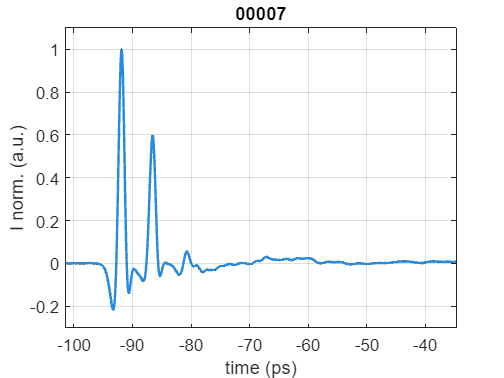

cmap1 = abyss(sweepNum);
% cmap1 = slanCM('cosmic',n0Idx); % requires the slanM add-on
cmap2 = lines(n0Idx);

figure;
ax = axes;

hold on;
for j = 1:n0Idx
    for i = 1:sweepNum
        plot(delayTime,squeeze(transients(:,i,j)),'LineWidth',2, ...
           'Color',cmap1(i,:));
    end
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
ylim([-0.3 1.1]);
xlabel('time (ps)');
ylabel('I norm. (a.u.)');
title(fileID);

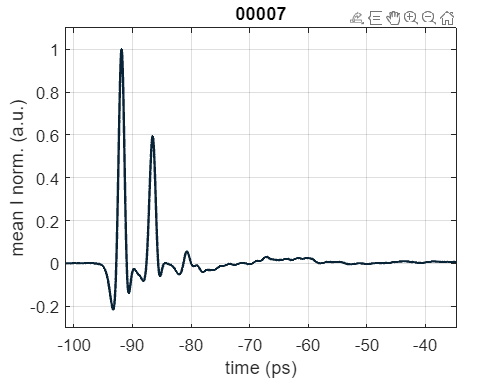


figure;
ax = axes;

hold on;
for j = 1:n0Idx
    % scatter(delayTime,transients(:,:,j),2,[0 0.4470 0.7410], ...
        % 'filled','MarkerFaceAlpha',0.5);
    % plot(delayTime,transientsSweepMean(:,j),'LineWidth',2, ...
       % 'Color',[0.6353 0.0784 0.1843]);
   plot(delayTime,transientsSweepMean(:,j),'LineWidth',2, ...
       'Color',cmap1(j,:),'DisplayName',[num2str(n0(j),3),' V']);
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
ylim([-0.3 1.1]);
xlabel('time (ps)');
ylabel('mean I norm. (a.u.)');
title(fileID);

## Plot Emitter Current

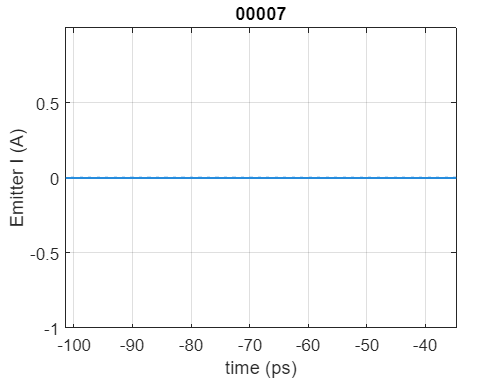

figure;
ax = axes;

hold on;
for i = 1:sweepNum
    plot(delayTime,squeeze(emitterCurrent(:,i)),'LineWidth',2, ...
        'Color',cmap1(i,:));
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
% ylim([-10 10]);
xlabel('time (ps)');
ylabel('Emitter I (A)');
title(fileID);

## Plot Stage Data

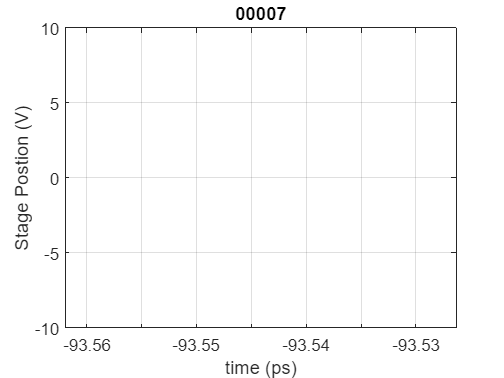

figure;
ax = axes;

hold on;
for i = 1:sweepNum
    plot(delayTime,squeeze(stagePos(:,i)),'LineWidth',2, ...
        'Color',cmap1(i,:));
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
ylim([-10 10]);
xlabel('time (ps)');
ylabel('Stage Postion (V)');
title(fileID);

## Compute FFT 

% t1 = 190; % in ps
% t2 = 220; % in ps
% [mt1, t1Idx] = min(abs(delayTime-t1));
% [mt2, t2Idx] = min(abs(delayTime-t2));
t1Idx = 1; % in index
t2Idx = 400; % in index

n = 2^nextpow2(t2Idx-t1Idx);
Fs = n/(delayTime(t2Idx)-delayTime(t1Idx));
df = Fs/n;
f = -Fs/2:df:Fs/2-df + (df/2)*mod(n,2);
f_idx = find(f>1.5 & f<2.0);

transientsFFT = fftshift(fft(transients(t1Idx:t2Idx-1,:,:),n,1));
transientsFFTMean = squeeze(mean(transientsFFT,2));

## Plot Window

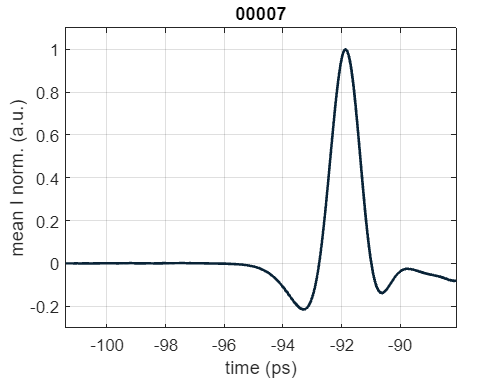

figure;
ax = axes;

for j = 1:n0Idx
    for i = 1:sweepNum
        plot(delayTime(t1Idx:t2Idx),transients(t1Idx:t2Idx,i,j),'LineWidth',2, ...
            'Color',cmap1(j,:));
        hold on;
    end
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
axis tight;
ylim([-0.3 1.1]);
xlabel('time (ps)');
ylabel('mean I norm. (a.u.)');
title(fileID);

## Plot FFT

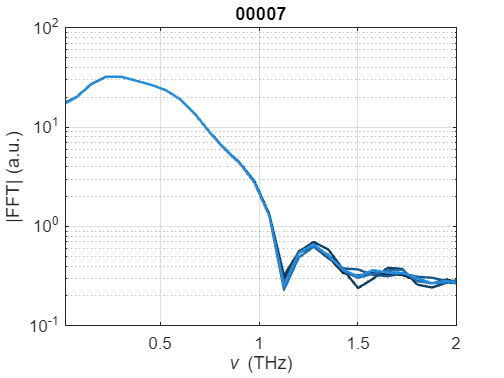

figure;
ax = axes;

for j = 1:n0Idx
    for i = 1:sweepNum
        semilogy(f,abs(squeeze(transientsFFT(:,i,j))),'LineWidth',2, ...
            'Color',cmap1(i,:),'DisplayName',[num2str(n0(j),3),' V']);
        hold on;
    end
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
xlim([0.02 2.0]);
ylim([0.1 100.0]);
xlabel('\nu (THz)');
ylabel('|FFT| (a.u.)');
title(fileID);

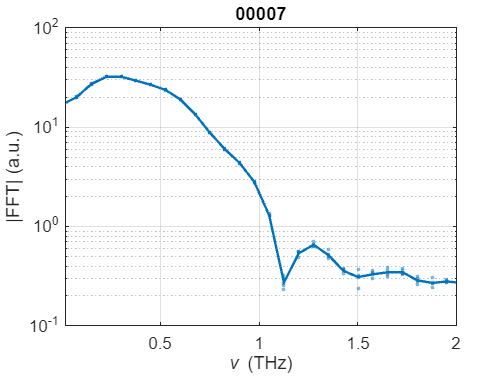



figure;
ax = axes;

for j = 1:n0Idx
    semilogy(f,abs(transientsFFTMean(:,j)),'LineWidth',2, ...
        'Color',cmap2(j,:),'DisplayName',[num2str(n0(j),3),' V']);
    hold on;
    scatter(f,abs(squeeze(transientsFFT(:,:,j))),10,[0 0.4470 0.7410], ...
        'filled','MarkerFaceAlpha',0.5);
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
xlim([0.02 2.0]);
ylim([0.1 100.0]);
xlabel('\nu (THz)');
ylabel('|FFT| (a.u.)');
title(fileID);

## Plot FFT ratio

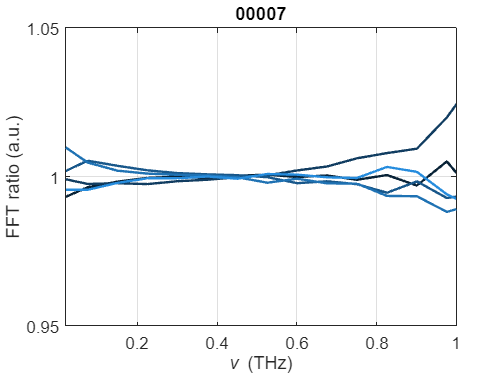

figure;
ax = axes;

hold on;

for j = 1:n0Idx
    for i = 1:sweepNum
        plot(f,abs(transientsFFT(:,i,j))./abs(transientsFFTMean(:,1,1)),'LineWidth',2, ...
            'Color',cmap1(i,:), 'DisplayName',num2str(n0(j),2));
    end
end

hold off;
ax.FontSize = 14;
box on;
grid on;
% legend('Location','best');
axis tight;
xlim([0.02 1.0]);
ylim([0.95 1.05]);
xlabel('\nu (THz)');
ylabel('FFT ratio (a.u.)');
title(fileID);